## Inizializzazione

clear all
close all
clc

numNodes = 45;
numVehicles = 4;
capacity = [2010 2010 2010 2010];
demand = [0 33 15 10 40 15 5 77 435 165 120 65 23 18 550 78 627 9 96 116 116 83 41 645 694 573 1 181 106 52 117 52 1300 57 28 84 1 54 19 88 41 238 66 44 42];
East = [0 3 2.5 48 48 69 70 64 3 2.5 -13 -20 -9 -8.5 -8 2 -2 -10 -20 -15 5 -4.5 -52 -53 0 -30 -51 81 84 82 40 50 51 63 45 54 29 21 22 39 39.5 40 28 24 24];
North = [0 5 9 16 17 16 16 13 -22 1 11.5 45 52 53 52 2 9 20 19 -21 9 -9 -36 -36 0.01 -18 -35 9 -99 -6 -12 -7 -8 -17 -1 8.5 4 3 2 -3 -3 -11 -2 -18 -19];
distance = zeros(numNodes, numNodes);
for i = 1:numNodes
    for j = 1:numNodes
       distance(i,j) = round(10 * sqrt(((East(i) - East(j)).^2) + ((North(i) - North(j)).^2)));
    end
end

## Metodo costruttivo

res_capacity = [2010 2010 2010 2010];
[routes,seeds] = insertion_method(res_capacity, demand, distance);

obj_function(routes,distance)

ans = 7654

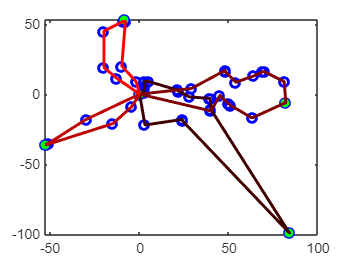

plot(East, North, 'bo', East(seeds), North(seeds), 'g*', 'linewidth',2)
hold on
for j = 1:numVehicles
    plot(East(routes{j}), North(routes{j}), '-', 'Color', [j/numVehicles 0 0], 'linewidth',2)
    hold on
end
hold off

## Metodo iterativo

capacity = [2010 2010 2010 2010];
Nmax = 50*numNodes;
amax = 5;
bmax = 3;
M = 2;
P = 2;
tmin = 5;
tmax = 10;

[RoutesList] = tabu_search(Nmax, amax, bmax, M, P, tmin, tmax, distance, demand, capacity, routes, East, North);
obj_function(RoutesList,distance)

ans = 7303

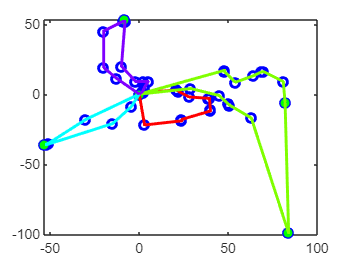


plot(East, North, 'bo', East(seeds), North(seeds), 'g*', 'linewidth',2)
hold on
cmap = hsv(numVehicles);
for j = 1:numVehicles
    plot(East(RoutesList{j}), North(RoutesList{j}), '-', 'Color', cmap(j,:), 'linewidth',2)
    hold on
end
hold off